# **Controller design for the motors**

## **Motor parameters and t.f.**

First we define the motor paramters and it's transfer function

R = 4.1; 
L = 4.1e-3; 
Kb = 0.0074;
Kt = Kb; 
D = 0.93e-6; 
J = 1.01e-6;

Ts = 0.004;
transport_delay = 0.01;

Gn = Kt;
Gd = [J*L, D*L+J*R, D*R + Kt*Kb];
G = minreal(tf(Gn, Gd));
G.OutputDelay = transport_delay;
Gz = c2d(G, Ts,'zoh');

## PI Controller

Then we design the PI controller:


$$C(s) = K_P + \frac{K_I}{s} = \frac{K_Ps + K_I}{s} = K_P \frac{s + \frac{K_I}{K_P}}{s} = K_P \frac{s + z_1}{s}$$


And so:


$$K_I = z_1 \cdot K_P$$


The design of this controller can be done with *sisotool*, by choosing a compensator with 1 integrator and 1 real zero.

%sisotool(Gz)

s = tf('s');
z = tf('z', Ts);

% From sisotool tuning
%Cz_sisotool = (0.0095439*(z-0.9465))/(z-1);
Cz_sisotool = (1.5869e-05*(z+1))/(z-1);
C = zpk(d2c(Cz_sisotool))

C =
 
  1.5869e-05 (s+500)
  ------------------
          s
 
Continuous-time zero/pole/gain model.
Model Properties



num = tfdata(C, 'v');

Kp = num(1)

Kp = 1.5869e-05

Ki = -zero(C)*Kp

Ki = 0.0079

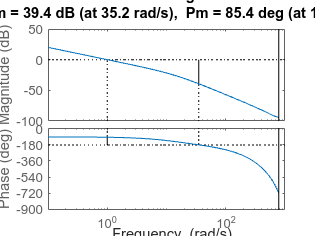


C = Ki/s + Kp;
Cz = c2d(C, Ts, 'tunstin');

P = Cz*Gz;

figure; margin(P);


step(feedback(P,1), 5);

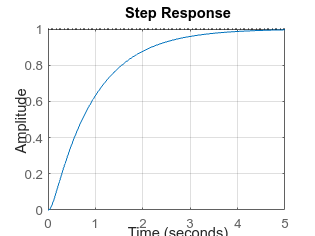

C =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 0.0343, Ki = 0.0361, Ts = 0.004
 
Sample time: 0.004 seconds
Discrete-time PI controller in parallel form.
Model Properties


info = struct with fields:
                Stable: 1
    CrossoverFrequency: 60
           PhaseMargin: 57.7046


grid on